T_stop = 0.5000

C_r = 0.0015

V_s_data =     1.0546    1.4798    1.9134    2.3264    2.7441    3.1787    3.6011
    1.0405    1.4582    1.8619    2.2552    2.6524    3.0363    3.4438
    0.9637    1.3524    1.7223    2.0923    2.4641    2.8472    3.2386
    1.0518    1.4629    1.8722    2.2880    2.7123    3.1281    3.5421
    1.0199    1.4180    1.8151    2.2300    2.6271    3.0298    3.4494
    0.9974    1.3927    1.8029    2.1972    2.5924    3.0064    3.4082


R_s = 6.7500

Number of simulations: 50


[14-Jul-2026 20:40:59] Checking for availability of parallel pool...
[14-Jul-2026 20:41:00] Starting Simulink on parallel workers...
[14-Jul-2026 20:41:01] Configuring simulation cache folder on parallel workers...
[14-Jul-2026 20:41:01] Transferring base workspace variables used in the model to parallel workers...
[14-Jul-2026 20:41:01] Loading model on parallel workers...
[14-Jul-2026 20:41:06] Running simulations...
[14-Jul-2026 20:42:01] Completed 1 of 50 simulation runs
[14-Jul-2026 20:42:03] Completed 2 of 50 simulation runs
[14-Jul-2026 20:42:03] Completed 3 of 50 simulation runs
[14-Jul-2026 20:42:03] Completed 4 of 50 simulation runs
[14-Jul-2026 20:42:52] Completed 5 of 50 simulation runs
[14-Jul-2026 20:42:52] Completed 6 of 50 simulation runs
[14-Jul-2026 20:42:53] Completed 7 of 50 simulation runs
[14-Jul-2026 20:42:55] Completed 8 of 50 simulation runs
[14-Jul-2026 20:43:43] Completed 9 of 50 simulation runs
[14-Jul-2026 20:43:45] Completed 10 of 50 simulation runs
[14-Ju

Number of simulations: 50


[14-Jul-2026 20:51:53] Checking for availability of parallel pool...
[14-Jul-2026 20:51:54] Starting Simulink on parallel workers...
[14-Jul-2026 20:51:54] Configuring simulation cache folder on parallel workers...
[14-Jul-2026 20:51:54] Transferring base workspace variables used in the model to parallel workers...
[14-Jul-2026 20:51:55] Loading model on parallel workers...
[14-Jul-2026 20:52:00] Running simulations...
[14-Jul-2026 20:52:57] Completed 1 of 50 simulation runs
[14-Jul-2026 20:52:59] Completed 2 of 50 simulation runs
[14-Jul-2026 20:52:59] Completed 3 of 50 simulation runs
[14-Jul-2026 20:52:59] Completed 4 of 50 simulation runs
[14-Jul-2026 20:53:50] Completed 5 of 50 simulation runs
[14-Jul-2026 20:53:50] Completed 6 of 50 simulation runs
[14-Jul-2026 20:53:53] Completed 7 of 50 simulation runs
[14-Jul-2026 20:53:53] Completed 8 of 50 simulation runs
[14-Jul-2026 20:54:40] Completed 9 of 50 simulation runs
[14-Jul-2026 20:54:41] Completed 10 of 50 simulation runs
[14-Ju

Number of simulations: 50


[14-Jul-2026 21:03:01] Checking for availability of parallel pool...
[14-Jul-2026 21:03:01] Starting Simulink on parallel workers...
[14-Jul-2026 21:03:01] Configuring simulation cache folder on parallel workers...
[14-Jul-2026 21:03:01] Transferring base workspace variables used in the model to parallel workers...
[14-Jul-2026 21:03:03] Loading model on parallel workers...
[14-Jul-2026 21:03:15] Running simulations...
[14-Jul-2026 21:04:16] Completed 1 of 50 simulation runs
[14-Jul-2026 21:04:17] Completed 2 of 50 simulation runs
[14-Jul-2026 21:04:18] Completed 3 of 50 simulation runs
[14-Jul-2026 21:04:18] Completed 4 of 50 simulation runs
[14-Jul-2026 21:05:08] Completed 5 of 50 simulation runs
[14-Jul-2026 21:05:09] Completed 6 of 50 simulation runs
[14-Jul-2026 21:05:10] Completed 7 of 50 simulation runs
[14-Jul-2026 21:05:11] Completed 8 of 50 simulation runs
[14-Jul-2026 21:06:00] Completed 9 of 50 simulation runs
[14-Jul-2026 21:06:00] Completed 10 of 50 simulation runs
[14-Ju

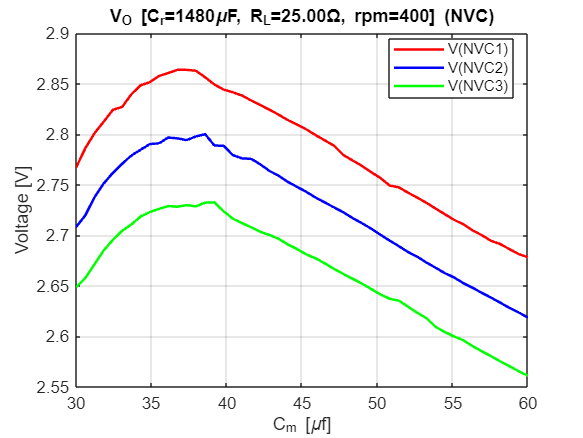

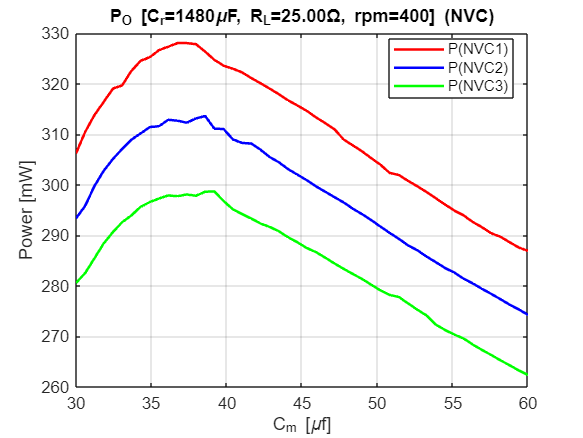

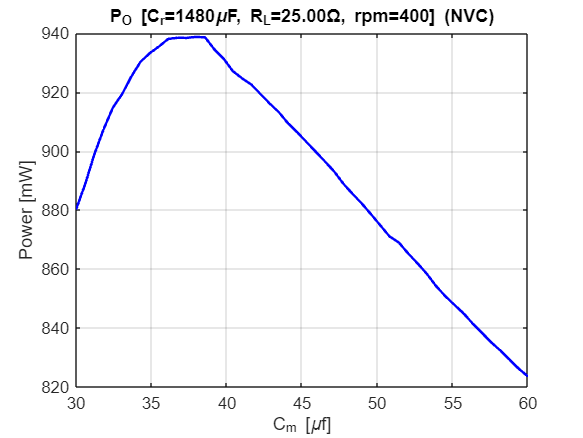

Elapsed time is 2251.754059 seconds.


%%%%%%%%%%%% Claude inserisci qui i vettori dei dati dalle misurazioni %%%%%%%%%%%%






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


figure;
plot(R_L, P_real_b1*1000, 'r-', 'LineWidth', 1.5);hold on;
plot(R_L, P_real_b2*1000, 'b-', 'LineWidth', 1.5);
plot(R_L, P_real_b3*1000, 'g-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (FWR)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L), max(R_L)]);
legend(["P(NVC1)","P(NVC2)","P(NVC3)"], "Location","best");
hold off;

figure;
plot(R_L, (P_real_b1+P_real_b2+P_real_b3)*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (FWR)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L), max(R_L)]);
hold off;